# Longitudinal Vehicle Properties

This script collects block parameters from Longitudinal Vehicle block and plots vehicle properties. Longitudinal Vehicle block is part of Simscape Driveline.

## Resisting Force and Power

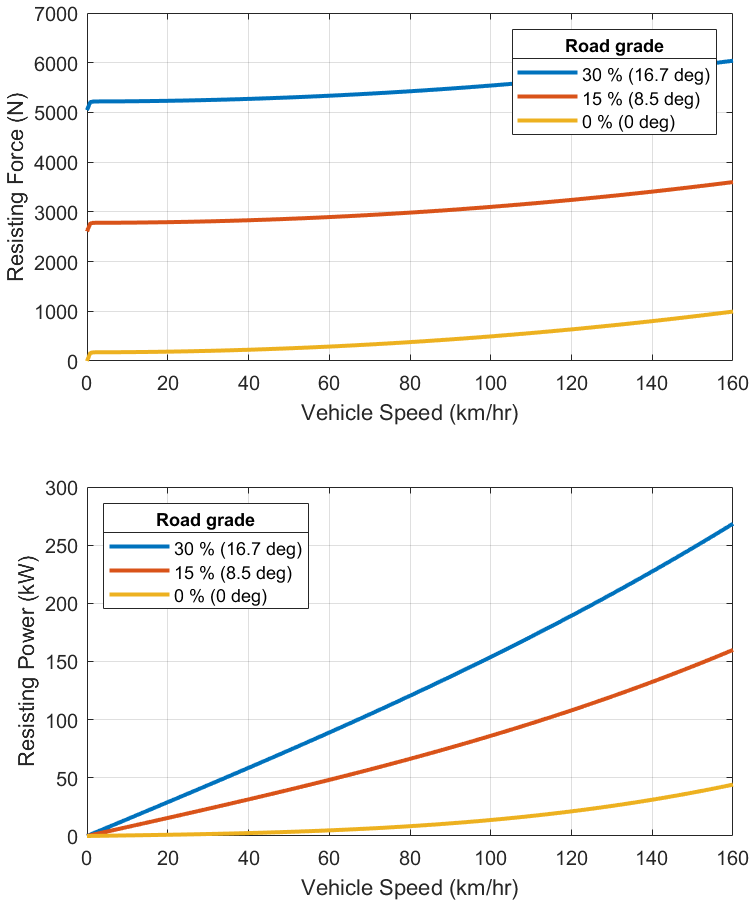

refsub = "Vehicle1D_refsub_Driveline";
name = "Vehicle1D_Driveline";

if not(bdIsLoaded(refsub))
  load_system(refsub)
end

% Load parameters.
Vehicle1D_harness_setup

% Select subsystem.
set_param(0, CurrentSystem = refsub)

% Select block.
set_param(gcs, CurrentBlock = "Longitudinal Vehicle")

% Collect block parameters.
block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);

fig = Vehicle1DUtility.plotRoadLoad( ...
  VehicleMass_kg = block_info.M_e_kg, ...
  RoadLoadA_N = block_info.A_rl_N, ...
  RoadLoadB_N_per_kph = block_info.B_rl_N_per_kph, ...
  RoadLoadC_N_per_kph2 = block_info.C_rl_N_per_kph2, ...
  GravitationalAcceleration_m_per_s2 = block_info.grav_m_per_s2, ...
  VehicleSpeedVector_kph = linspace(0, 160, 200), ...
  RoadGradeVector_pct = [30, 15, 0] );

fig.Position(3:4) = [500 600];  % Width height

imgPath = fullfile( currentProject().RootFolder, "Components", ...
  "Vehicle1D", "images", "image_"+name+"_ResistingForcePower.png");

exportgraphics(fig, imgPath)

*Copyright 2022 The MathWorks, Inc.*